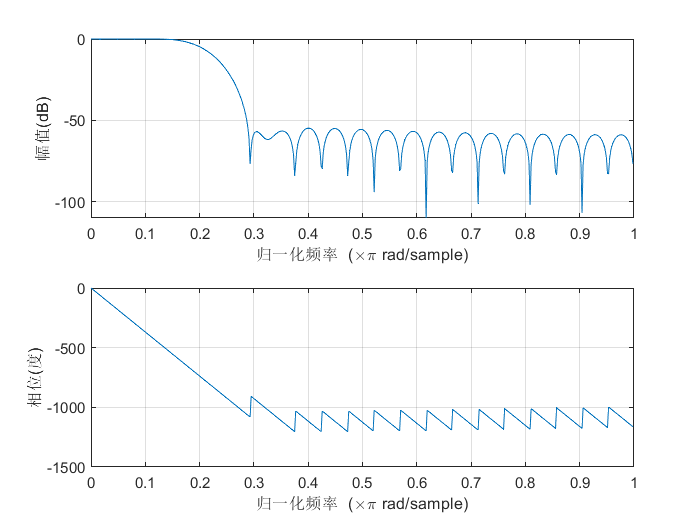

clc 
clear all 
close all 

[y, fs] = audioread("test_16k.wav"); 

frame_length = 10 * fs / 1e3; 
frame_shift = 5 * fs / 1e3; 


window = hamming(frame_length); 

frame_mat = enframe(y, window, frame_shift); 
frame_num = size(frame_mat, 1); 
[zcr] = deal(zeros(frame_num, frame_length));
for i = 1:frame_num
    zcr(i,:) = zerocrossing(frame_mat(i,:)) / frame_length; 
end


% Deframe_matn linear filter
Wp = [0.1 * fs] ./ (fs / 2); Ws = [0.2 * fs] ./ (fs / 2); Rp = 3; Rs = 40; 
[~, Wn] = buttord(Wp, Ws, Rp, Rs); 
[b, a] = fir1(41, Wn); 
freqz(b, a); 

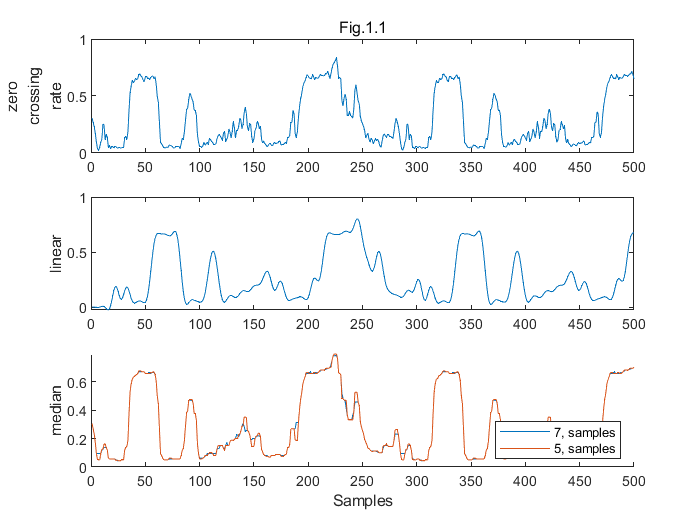


zcr = reshape(zcr, [frame_num*frame_length, 1]);
zcr_linear = filter(b, a, zcr);
zcr_median_7 = median_smoother(zcr, 7); 
zcr_median_5 = median_smoother(zcr, 5); 
zcr_combi_7 = filter(b, a, zcr_median_7); 
zcr_combi_5 = filter(b, a, zcr_median_5); 
zcr_combi2_7 = median_smoother(zcr_linear, 7); 
zcr_combi2_5 = median_smoother(zcr_linear, 5);

figure; 
subplot(311), plot(zcr(1:0.5e3)), ylabel("zero" +newline+"crossing" +newline+"rate"), title("Fig.1.1"); 
subplot(312), plot(zcr_linear(1:0.5e3)), ylabel("linear"); 
subplot(313), hold on; 
plot(zcr_median_7(1:0.5e3)), plot(zcr_median_5(1:0.5e3)),  xlabel("Samples"), ylabel("median"); 
legend(["7, samples", "5, samples"], 'Location', 'southeast'); 

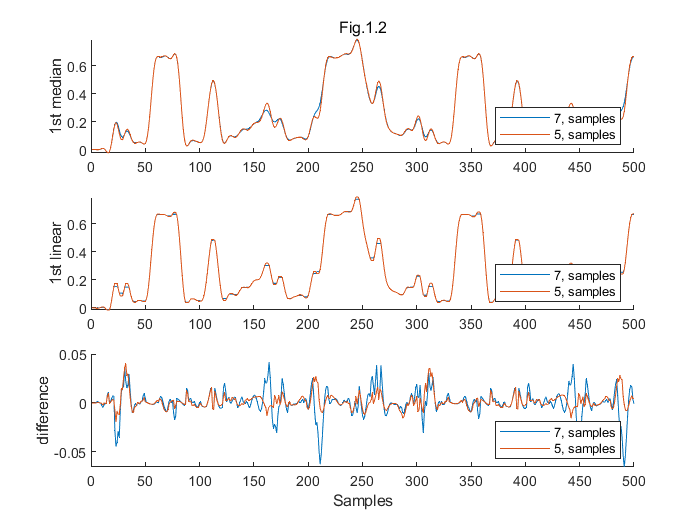

figure; 
subplot(311), hold on; 
plot(zcr_combi_7(1:0.5e3)), plot(zcr_combi_5(1:0.5e3)), ylabel("1st median"), title("Fig.1.2"); 
legend(["7, samples", "5, samples"], 'Location', 'southeast'); 
subplot(312), hold on; 
plot(zcr_combi2_7(1:0.5e3)), plot(zcr_combi2_5(1:0.5e3)), ylabel("1st linear"); 
legend(["7, samples", "5, samples"], 'Location', 'southeast'); 
subplot(313), hold on; 
plot(zcr_combi2_7(1:0.5e3) - zcr_combi_7(1:0.5e3)), plot(zcr_combi2_5(1:0.5e3) - zcr_combi_5(1:0.5e3)), xlabel("Samples"), ylabel("difference"); 
legend(["7, samples", "5, samples"], 'Location', 'southeast'); 